# MSessionExplorer.SliceEventTimes

# MSessionExplorer.SliceTimeSeries

Ignore code in this section

if exist('isRun', 'var') && exist('seRaw', 'var') && isRun
    se = seRaw.Duplicate;
    se.isVerbose = false;
    se.SetColumn('adc', 'tubeV', @(x) x-median(x), 'all');
    randomTable = se.GetTable('hsv');
    randomTable.Properties.VariableNames = {'time', 'Var1', 'Var2', 'Var3'};
    tRef = se.GetReferenceTime();
else
    edit MSessionExplorer.Examples.SliceEventTimes
    return;
end

**Description**

help MSessionExplorer.SliceEventTimes

  Return slices of event time data using time windows
 
    tbOut = SliceEventTimes(tbIn, tWin)
    tbOut = SliceEventTimes(tbIn, tWin, rowInd)
    tbOut = SliceEventTimes(tbIn, tWin, rowInd, colInd)
    tbOut = SliceEventTimes(..., 'Fill', 'none')
    tbOut = SliceEventTimes(..., 'ReferenceTime', [])
 
  Inputs
    tbIn                A table of event times data or the name of a eventTimes table in the object.
    tWin                1) An n-by-2 matrix where each row has the begin and end time of a window.
                        When n equals 1, this window is applied to every rows. When n equals the height
                        of the table or the number of selected rows, each window is applied to respective
                        row.
                        2) An n-element cell array where each element is a m-by-2 matrix of time windows.
                        n must equal to the height of th

help MSessionExplorer.SliceTimeSeries

  Return slices of time series data using time windows
 
    tbOut = SliceTimeSeries(tbIn, tWin)
    tbOut = SliceTimeSeries(tbIn, tWin, rowInd)
    tbOut = SliceTimeSeries(tbIn, tWin, rowInd, colInd)
    tbOut = SliceTimeSeries(..., 'Fill', 'none')
    tbOut = SliceTimeSeries(..., 'ReferenceTime', [])
 
  Inputs
    tbIn                A table of time series data or the name of a timeSeries table in the object.
    tWin                1) An n-by-2 matrix where each row has the begin and end time of a window.
                        When n equals 1, this window is applied to every rows. When n equals the height
                        of the table or the number of selected rows, each window is applied to respective
                        row. Inf values will be substituted by min or max time available, respectively.
                        2) An n-element cell array where each element is a m-by-2 matr

**Example 1**

**Slice a range of data out using a time window**

First, let's see how epochs are currently sliced. The plotted are the first 10 epochs in this session. Magenta dots show 'lickOn' events from 'behavTime' table. Lines show 'tubeV' time series from 'adc' table. 

se.Preview('behavTime', 'adc')

    cue      posIndex      water    opto       lickOn           lickOff   
    ___    ____________    _____    ____    _____________    _____________

     0     [6×1 double]    1.832    NaN     [20×1 double]    [20×1 double]
     0     [6×1 double]    1.788    NaN     [19×1 double]    [19×1 double]
     0     [6×1 double]     1.87    NaN     [21×1 double]    [21×1 double]
     0     [6×1 double]    1.755    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.891    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.742    NaN     [14×1 double]    [14×1 double]

          time             lickportV           lickportH             tubeV               tubeH      
    

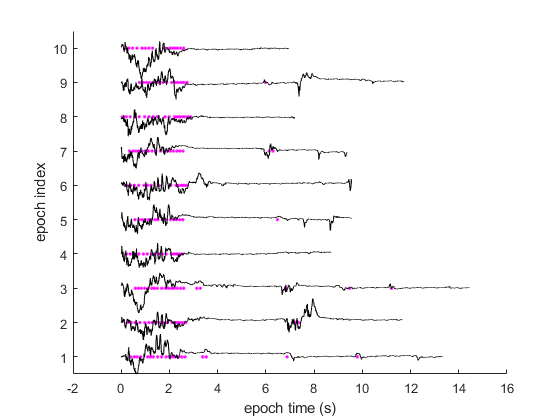


Visualize(se);

Now, we only want the data between 0s and 10s for each epoch. Since SliceEventTimes and SliceTimeSeries do not preserve data integrity and even the epoch structure (unlike e.g. AlignTime), they process one table at a time and return the new table as output. 

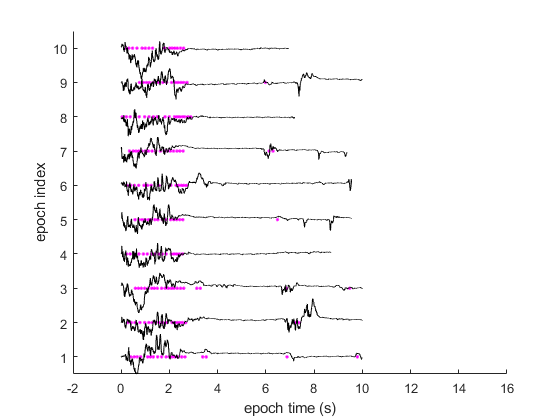

tWin = [0 10];

btSlice = se.SliceEventTimes('behavTime', tWin);
adcSlice = se.SliceTimeSeries('adc', tWin);

Visualize2(btSlice, adcSlice);

Some epoch do not have 10 seconds of data thus ended short. Those data belong to their next epochs. Here is the way to include them. 

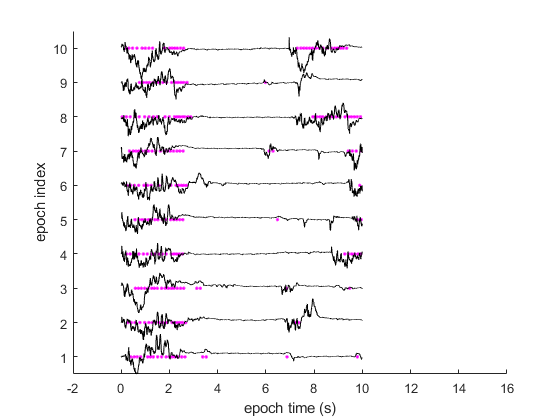

btSlice = se.SliceEventTimes('behavTime', tWin, 'Fill', 'bleed');
adcSlice = se.SliceTimeSeries('adc', tWin, 'Fill', 'bleed');

Visualize2(btSlice, adcSlice);

**Example 2**

**Use different time windows to slice specific epochs and columns**

Please see Example 1 about the original data. Here, we create 5 time windows to slice only 5 selected epochs, respectively, and 1 selected column. 

tWin = [0 2; 2 4; 4 6; 6 8; 8 10]

tWin =      0     2
     2     4
     4     6
     6     8
     8    10


row2slice = [1 3 5 7 9]'

row2slice =      1
     3
     5
     7
     9



btSlice = se.SliceEventTimes('behavTime', tWin, row2slice, {'lickOn'})

btSlice = 5×1 table
       lickOn    
    _____________

    [10×1 double]
    [ 7×1 double]
    [        NaN]
    [ 2×1 double]
    [        NaN]


adcSlice = se.SliceTimeSeries('adc', tWin, row2slice, {'tubeV'})

adcSlice = 5×2 table
         time               tubeV     
    _______________    _______________

    [2000×1 double]    [2000×1 single]
    [2000×1 double]    [2000×1 single]
    [2000×1 double]    [2000×1 single]
    [2000×1 double]    [2000×1 single]
    [2000×1 double]    [2000×1 single]


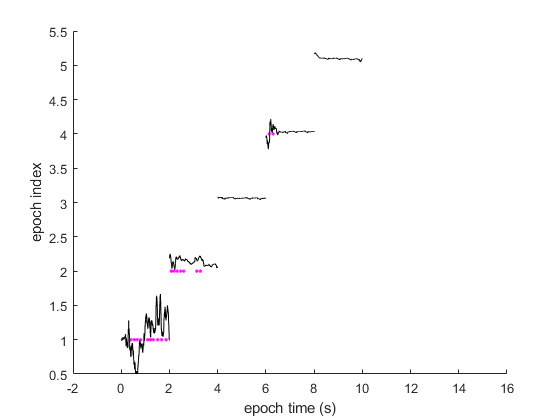


Visualize2(btSlice, adcSlice);

**Example 3**

**Use multiple time windows to slice each epoch**

Please see Example 1 about the original data. Here, we apply 5 time windows to each of the 2 selected epochs. That gives us 2 x 5 = 10 rows of data in the output. 

tWin = {[0 2; 2 4; 4 6; 6 8; 8 10]}

tWin = 1×1 cell array
    {5×2 double}


row2slice = [1 6]'

row2slice =      1
     6



btSlice = se.SliceEventTimes('behavTime', tWin, row2slice)

btSlice = 10×6 table
    cue      posIndex      water    opto       lickOn           lickOff   
    ___    ____________    _____    ____    _____________    _____________

      0    [6×1 double]    1.832    NaN     [10×1 double]    [10×1 double]
    NaN    [       NaN]      NaN    NaN     [ 8×1 double]    [ 8×1 double]
    NaN    [       NaN]      NaN    NaN     [        NaN]    [        NaN]
    NaN    [       NaN]      NaN    NaN     [     6.8770]    [     6.9080]
    NaN    [       NaN]      NaN    NaN     [     9.7950]    [     9.8190]
      0    [6×1 double]    1.742    NaN     [ 8×1 double]    [ 8×1 double]
    NaN    [       NaN]      NaN    NaN     [ 6×1 double]    [ 6×1 double]
    NaN    [       NaN]      NaN    NaN     [        NaN]    [        NaN]
    NaN    [       NaN] 

adcSlice = se.SliceTimeSeries('adc', tWin, row2slice)

adcSlice = 10×5 table
         time             lickportV          lickportH            tubeV              tubeH     
    _______________    _______________    _______________    _______________    _______________

    [2000×1 double]    [2000×1 single]    [2000×1 single]    [2000×1 single]    [2000×1 single]
    [2000×1 double]    [2000×1 single]    [2000×1 single]    [2000×1 single]    [2000×1 single]
    [2000×1 double]    [2000×1 single]    [2000×1 single]    [2000×1 single]    [2000×1 single]
    [2000×1 double]    [2000×1 single]    [2000×1 single]    [2000×1 single]    [2000×1 single]
    [2000×1 double]    [2000×1 single]    [2000×1 single]    [2000×1 single]    [2000×1 single]
    [2000×1 double]    [2000×1 single]    [2000×1 single]    [2000×1 single]    [2000×1 single]
    [2000×1 double]    [2000×1 single] 

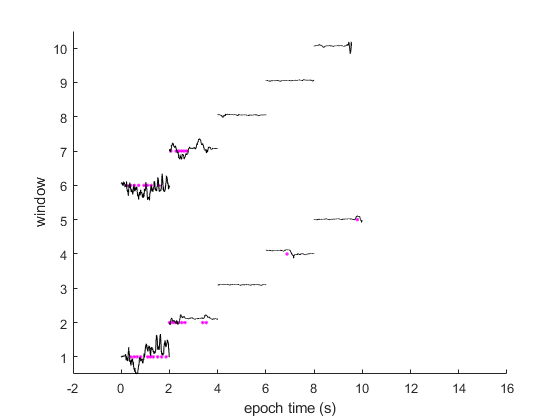


Visualize2(btSlice, adcSlice); ylabel('window');

**Example 4**

**Slice a table unrelated to the object**

We use an arbitrary timeSeries table as an example. Note that reference times need to be provided for the 'bleed' option. 

head(randomTable)

ans = 8×4 table
         time                Var1               Var2               Var3      
    _______________    ________________    _______________    _______________

    [1563×1 double]    [1563×1 logical]    [1563×1 single]    [1563×4 single]
    [1547×1 double]    [1547×1 logical]    [1547×1 single]    [1547×4 single]
    [1578×1 double]    [1578×1 logical]    [1578×1 single]    [1578×4 single]
    [1535×1 double]    [1535×1 logical]    [1535×1 single]    [1535×4 single]
    [1587×1 double]    [1587×1 logical]    [1587×1 single]    [1587×4 single]
    [1528×1 double]    [1528×1 logical]    [1528×1 single]    [1528×4 single]
    [1486×1 double]    [1486×1 logical]    [1486×1 single]    [1486×4 single]
    [1564×1 double]    [1564×1 logical]    [1564×1 single]    [1564×4 single]



slicedTable = se.SliceTimeSeries(randomTable, [1 3]);
head(slicedTable)

ans = 8×4 table
         time              Var1               Var2              Var3     
    ______________    _______________    ______________    ______________

    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]
    [800×1 double]    [800×1 logical]    [800×1 single]    [800×4 single]



slicedTable = se.SliceTimeSeries(randomTable, [1 3], 'Fill', 'bleed', 'ReferenceTime', tRef);


**Helper functions**

function Visualize(se)
[bt, adc] = se.GetTable('behavTime', 'adc');
Visualize2(bt, adc);
end

function Visualize2(bt, adc)
ind = 1:min(10, height(bt));
figure; clf
MPlot.PlotRaster(bt.lickOn(ind), ind, 'Color', 'm');
MPlot.PlotTraceLadder(adc.time(ind), adc.tubeV(ind), ind, 'Color', 'k');
xlim([-2 16]);
ylim([ind(1)-0.5 ind(end)+0.5]);
xlabel('epoch time (s)');
ylabel('epoch index');
box off
end